% This is the code for the prism

clc
clear 

disp('Define length of the area in x & y directions in meters for eg. x1 = 0:150:16000 & y1 = -10000:150:10000')

Define length of the area in x & y directions in meters for eg. x1 = 0:150:16000 & y1 = -10000:150:10000


x1 = -10:0.3:10; % input('Enter x value  ');  % Define total x distance with spacing
y1 = -10:0.3:10; % input('Enter y value  ');    % Define total y distance with spacing

disp('Define the observation plane in terms of z for eg. 20 and  2.7 density in gm/cc')

Define the observation plane in terms of z for eg. 20 and  2.7 density in gm/cc


z = 5; % input('Enter z-plane  ');   % the surface where data is computed

d = 11.11; % input('Enter d value  ');    % geological density in gm/cc
[x,y] = meshgrid(x1,y1);
A = 10^-3; % unit conversion from m to km
B = 1000; % unit conversion from mGal/km to E
% Predifed output parameters
% gz1 = zeros(size(x)); 
% gy1 = zeros(size(x));
% gx1 = zeros(size(x));
% Defining the prism model parameters and its edges
disp('Define the body parameters in meters for eg. xpos(1) = 4000; xpos(2) = 12000; ypos(1) = -2000; ypos(2) = 2000; zpos(1) = -1000; zpos(2) = -3000')

Define the body parameters in meters for eg. xpos(1) = 4000; xpos(2) = 12000; ypos(1) = -2000; ypos(2) = 2000; zpos(1) = -1000; zpos(2) = -3000


xpos(1) = 0; % input('Enter xpos1  '); % % first corner of body along x-axis
xpos(2) = 2; % input('Enter xpos2  ');   %second corner of body along x-axis
ypos(1) = 0; % input('Enter ypos1  ');  % first corner of body along y-axis
ypos(2) = 2; % input('Enter ypos2  ');  % second corner of body along y-axis
zpos(1) = 0; % input('Enter zpos1  ');  % first corner of body along downward z-axis
zpos(2) = 2; % input('Enter zpos2  ');  % second corner of body along downward z-axis
[gz1, gy1, gx1] = prismgrav(x, y, z, d, xpos, ypos, zpos);


disp('Results are in mGal and E')  

Results are in mGal and E


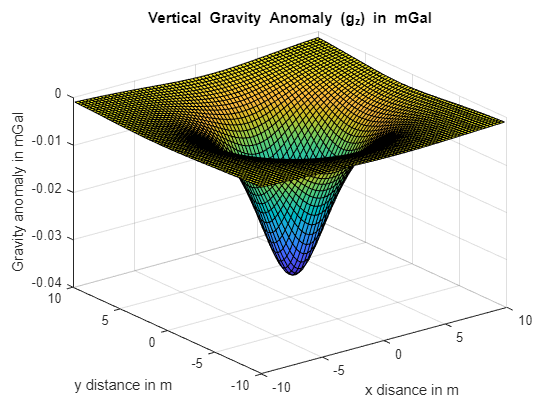

% plotting the responses
surf(x,y,gz1);  % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity anomaly in mGal');   % title for the anomaly axis
title('Vertical Gravity Anomaly (g_z) in mGal');   % title for the plot

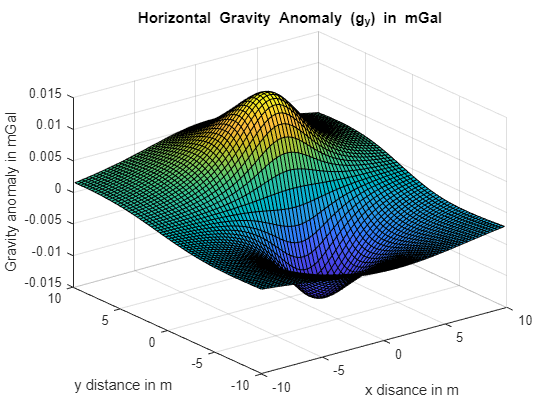

% plotting new figure
figure;
surf(x,y,gy1);  % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity anomaly in mGal');   % title for the anomaly axis
title('Horizontal Gravity Anomaly (g_y) in mGal');   % title for the plot

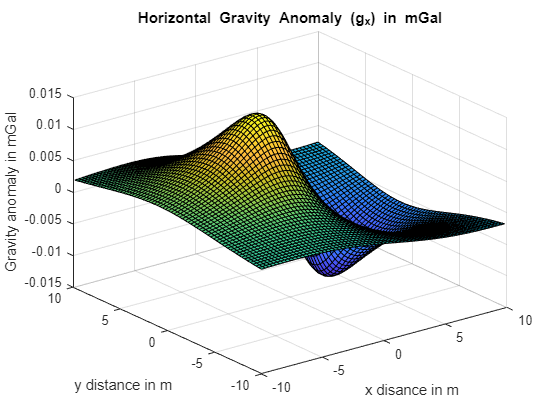

% plotting new figure
figure;
surf(x,y,gx1);   % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity anomaly in mGal');   % title for the anomaly axis
title('Horizontal Gravity Anomaly (g_x) in mGal');  % title for the plot

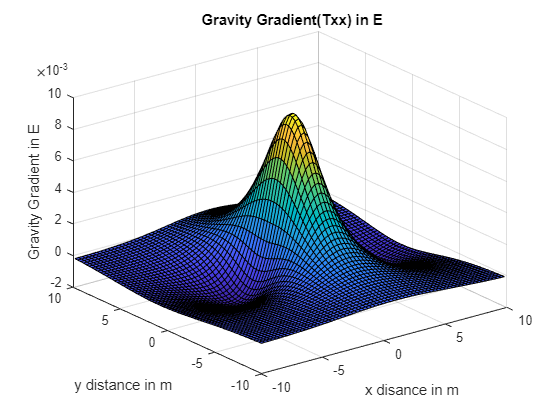


[gxx, gxy, gyy, gzx, gyz, gzz] = prismgrad(x, y, z, d, xpos, ypos, zpos);

% plotting the responses
figure;
surf(x,y,gxx);   % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity Gradient in E');  % title for the anomaly axis
title(' Gravity Gradient(Txx) in E');   % title for the plot

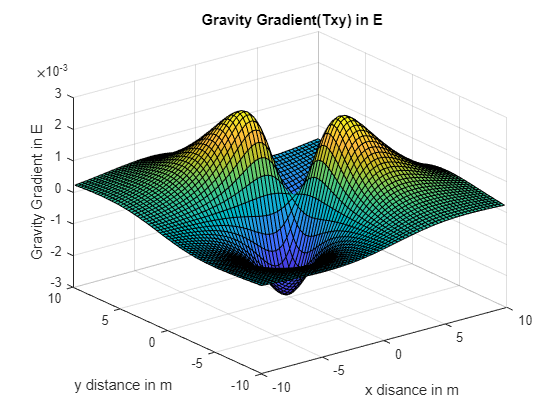

% plotting new figure
figure;
surf(x,y,gxy);    %3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity Gradient in E');  % title for the anomaly axis
title(' Gravity Gradient(Txy) in E');   % title for the plot

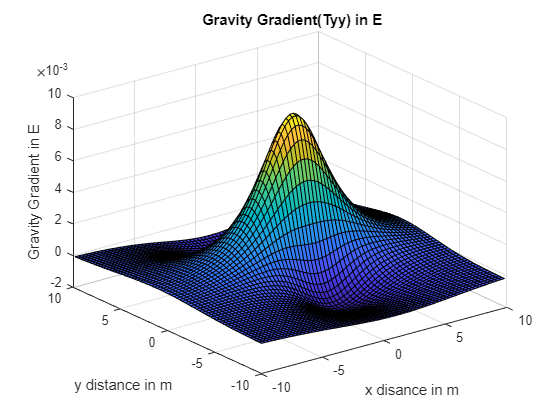

% plotting new figure
figure;
surf(x,y,gyy);   % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity Gradient in E');  % title for the anomaly axis
title(' Gravity Gradient(Tyy) in E');   % title for the plot

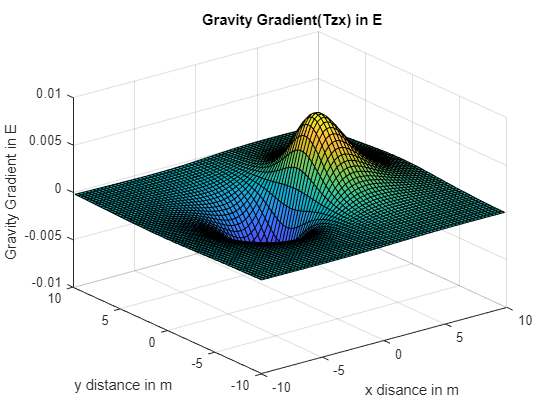

% plotting new figure
figure;
surf(x,y,gzx);     % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity Gradient in E');  % title for the anomaly axis
title(' Gravity Gradient(Tzx) in E');  % title for the plot

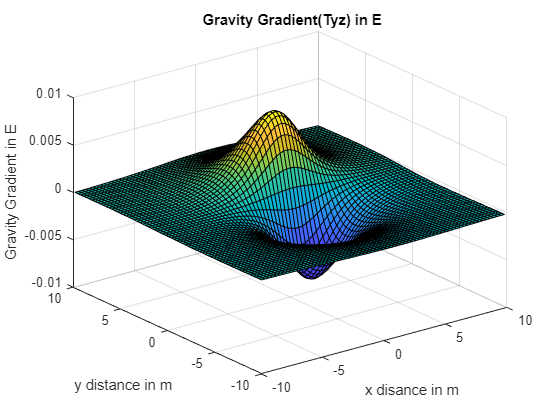

% plotting new figure
figure;
surf(x,y,gyz);    % 3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity Gradient in E');  % title for the anomaly axis
title(' Gravity Gradient(Tyz) in E');   % title for the plot

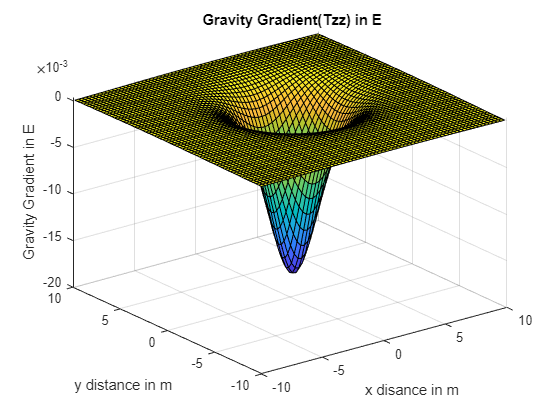

% plotting new figure
figure;
surf(x,y,gzz);   %3D plot
xlabel('x disance in m');   % title for the horizontal axis
ylabel('y distance in m');    % title for the vertical axis
zlabel('Gravity Gradient in E');  % title for the anomaly axis
title(' Gravity Gradient(Tzz) in E');  % title for the plot

function [gxx, gxy, gyy, gzx, gyz, gzz] = prismgrad(x, y, z, d, xpos, ypos, zpos)
G = 6.67384e-3;   % Define Gravitational constant
c = G*d;  % multiplication of gravitational constant and density 
% Predifed output parameters
gxx = zeros(size(x));
gxy = zeros(size(x));
gyy = zeros(size(x));
gzx = zeros(size(x));
gyz = zeros(size(x));
gzz = zeros(size(x));
val1 = zeros(size(x));
val2 = zeros(size(x));
% for the calculation of gravity effects due to all surfaces and corners of
% body
% computing the GGT components starting point
for i=1:2
    for j=1:2
        for k=1:2
                r=((x-xpos(i)).^2+(y-ypos(j)).^2+(z-zpos(k)).^2).^0.5;
                if mod(i+j+k,2)==0
                    s=1;
                else
                    s=-1;
                end
                valuexx = G*d*s*(atan(((x-xpos(i)).*(y-ypos(j)))./((x-xpos(i)).^2+(z-zpos(k)).*r+(z-zpos(k)).^2)));
                valuexy = G*d*s*(log(r+z-zpos(k)));
                valueyy = G*d*s*(atan(((x-xpos(i)).*(y-ypos(j)))./(r.^2+(z-zpos(k)).*r-(x-xpos(i)).^2)));
                valuezx = G*d*s.*(0.5*log((r-(y-ypos(j)))./(r+(y-ypos(j)))));
                valueyz = G*d*s.*(0.5*log((r-(x-xpos(i)))./(r+(x-xpos(i)))));
                valuezz =-G*d*s*atan((x-xpos(i)).*(y-ypos(j))./((z-zpos(k)).*r));
                value1 = ((valuezx.^2)*10^3 + (valueyz.^2)*10^3);
                value2 = ((valuezx.^2)*10^3 + (valueyz.^2)*10^3 + (valuezz.^2)*10^3);
                gxx = gxx + valuexx;
                gxy = gxy + valuexy;
                gyy = gyy + valueyy;
                gzx = gzx + valuezx;
                gyz = gyz + valueyz;
                gzz = gzz + valuezz;
                val1 = val1 + (value1).^0.5;
                val2 = val2 + (value2).^0.5;
            end
    end
end
end
  function [gz1, gy1, gx1] = prismgrav(x, y, z, d, xpos, ypos, zpos)
G = 6.67384e-3;   % Define Gravitational constant
c = G*d;  % multiplication of gravitational constant and density 
% for the calculation of gravity effects due to all surfaces and corners of
% body
%  starting point
gz1 = zeros(size(x)); 
gy1 = zeros(size(x));
gx1 = zeros(size(x));
for i = 1:2
    for j = 1:2
        for k = 1:2
            r = ((x-xpos(i)).^2 + (y-ypos(j)).^2 + (z-zpos(k)).^2).^0.5;
            if mod(i+j+k,2)==0
                s = 1;
            else
                s = -1;
            end
            gz = c*s*(((z-zpos(k)).*atan(((x-xpos(i)).*(y-ypos(j)))./((z-zpos(k)).*r))) - ((x-xpos(i)).*log(r+(y-ypos(j))))-((y-ypos(j)).*log(r+x-xpos(i))));
            gy = -c*s*((y-ypos(j)+1e-32).*atan(((z-zpos(k)).*(x-xpos(i)))./(((y-ypos(j)+1e-32).*r))) - ((z-zpos(k)).*log(r+x-xpos(i))+(x-xpos(i)).*log(r+z-zpos(k))));
            gx = c*s*(((x-xpos(i)).*atan(((y-ypos(j)+1e-32).*(z-zpos(k)))./(((x-xpos(i)).*r))) - ((y-ypos(j)+1e-32).*log(r+(z-zpos(k))))-((z-zpos(k)).*log(r+y-ypos(j)+1e-32))));
            gz1 = gz1 + gz;
            gy1 = gy1 + gy;
            gx1 = gx1 + gx;
        end
    end
end
end
